# Chap 8 Image generation

[llms-with-matlab/doc/functions/openAIImages.generate.md at main · matlab-deep-learning/llms-with-matlab](https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/doc/functions/openAIImages.generate.md)

### Dall-E 3 Generation

model = openAIImages(ModelName="dall-e-3") % By default Dall-E 2

model =   openAIImages with properties:

    ModelName: "dall-e-3"
      TimeOut: 10


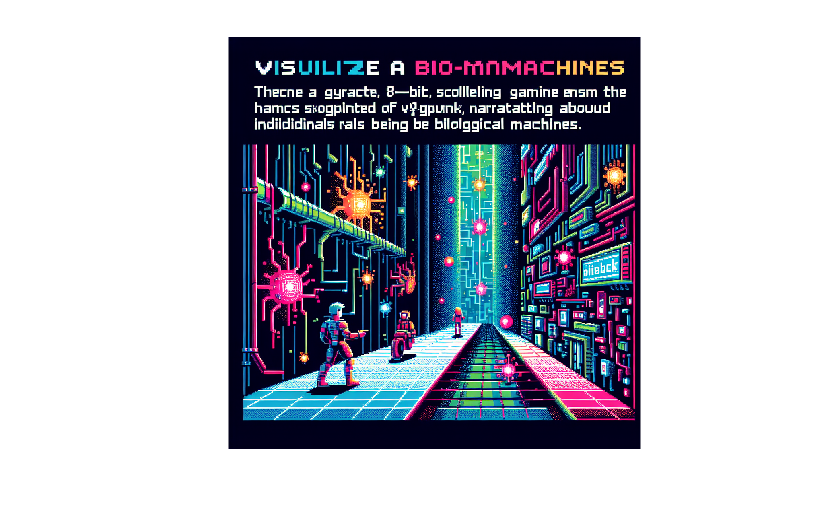

prompt = "An 8-bit pixelated game side scroller called biomachines." + ...
    "cyberpunk story about humans being biological machines." + ...
    "Pixelated like NES. Bright colors. Huge glowing pixels. Pixelated.";
Im = generate(model,prompt,"Size","1024x1024");
imshow(Im{1})

% Save image as png
imwrite(Im{1}, "biomachines-8bits_1024x1024_DallE3.png");